# Filters

# Audio Example

Here we load in a standard MATLAB sound file, 'handel'.

load handel
audiowrite('handel.wav',y,Fs)
[y, Fs] = audioread('handel.wav');
sound(y, Fs);
T = 1/Fs;
t = 0:T:(length(y)-1)*T;

Now we add a high-frequency (2500Hz) interference to the signal.

noise = 0.2*sin(2.*pi.*t.*2500).';
y = noise + y;
sound(y, Fs); 

We visualize the spectrum using a Fourier Transform.

N= 2^15;
S = fft(y,N);
S = fftshift(abs(S))/N;
F = Fs.*(-N/2:N/2-1)/N;

figure
plot(F,S)
title('Fourier Transform of Audio')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

# Filter Overview

## There are 4 main types of filters:

Lowpass - passes low frequencies through

Highpass - passes high frequencies through

Bandpass - passes a specific band

Bandstop - stops a specific band from going through

## There are primarily 4 implementations of filters

Butterworth - maxflat passband, monotonic passband & stopband

Chebychev I - equiripple passband, monotonic stopband

Chevychev II - monotonic passband, equiripple stopband

Elliptic - minimum order, equiripple passband & stopband

# Filter Design (GUI)

%filterDesigner

Error using 'status' with input argument of type 'handle.handle'.
Check for missing argument or incorrect argument data type.

Error in filterDesigner (line 438)
    status(hFDA, getString(message('signal:sigtools:siggui:Ready')));

Attenuation Pass = 1dB

Attenuation Stop = 80dB

Fpass = 1000

Fstop = 10000

Hd = getFilter
finalsound = step(Hd,y);
sound(finalsound,Fs);

# Filter Design (Code)

Generate a butterworth filter with Fs = 44100

Attenuation Pass = 1dB

Attenuation Stop = 80dB

Fpass = 1000

Fstop = 10000

Fs = 44100;
Apass = 1;
Astop = 80;
Fpass = 1e3;
Fstop = 1e4;
wpass = 2*Fpass/Fs; %normalized to nyquist freq.
wstop = 2*Fstop/Fs; %normalized to nyquist freq.


Other kinds of filters:

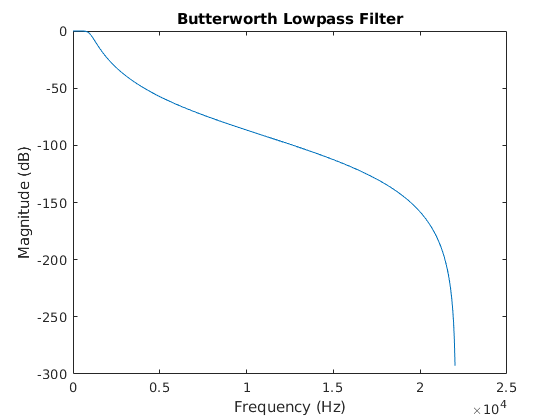

n = buttord([wpass],[wstop],Apass,Astop);
[b,a] = butter(n,[wpass]);
[H,W] = freqz(b,a);

% convert frequency to range 0 to Fs/2
f = W.*Fs/2/pi;
figure;
plot(f,20*log10(abs(H)));
title('Butterworth Lowpass Filter');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

# Image Example

## Low Pass Filtering

x = imread('pout.tif');
imshow(x);
x = double(x)/255;
[n,m] = ndgrid(0:7,0:7);
nnn = 1;
for nn = 0:7
    for mm = 0:7
        subplot(8,8,nnn)
        I = exp(1j*(n*nn+m*mm)/8);
        imagesc(real(I));
        axis square
        axis off
        nnn = nnn + 1;
    end
end

Error using matlab.ui.Root/set
There is no pixels property on the Root class.

Error in matlab.graphics.internal.clearNotify (line 28)
        matlab.internal.editor.FigureManager.figureBeingCleared(fig, flag);

Error in subplot (

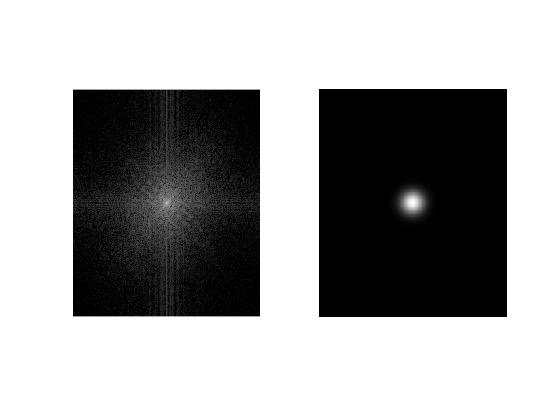

F = (fftshift(fft2(ifftshift(x))));
[H,W] = size(F);
[h,w] = ndgrid((1:H)-H/2,(1:W)-W/2);
hpf_mask = exp((-h.^2-w.^2)/200);
%hpf_mask(floor(H/2-H/10):floor(H/2+H/10),floor(W/2-W/10):floor(W/2+W/10)) = 1;

figure
subplot(121)
imshow(log(abs(F))/max(log(abs(F(:)))))
subplot(122)
imshow(hpf_mask)

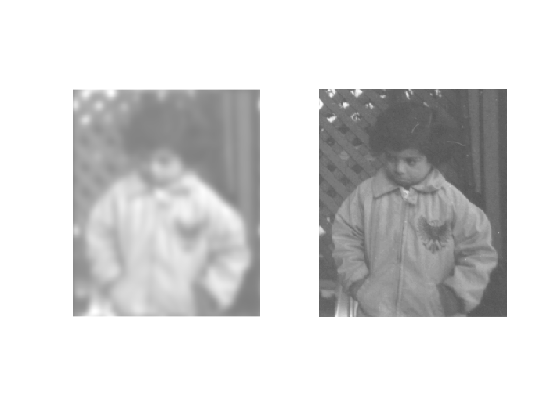


im_filtered_fft = hpf_mask.*F;
f = fftshift(ifft2(ifftshift(im_filtered_fft)));
subplot(121)
fnorm = abs(f)/max(abs(f(:)));
imshow(fnorm)
subplot(122)
xnorm = abs(double(x))/max(double(x(:)));
imshow(xnorm)

## Basic Edge Detection

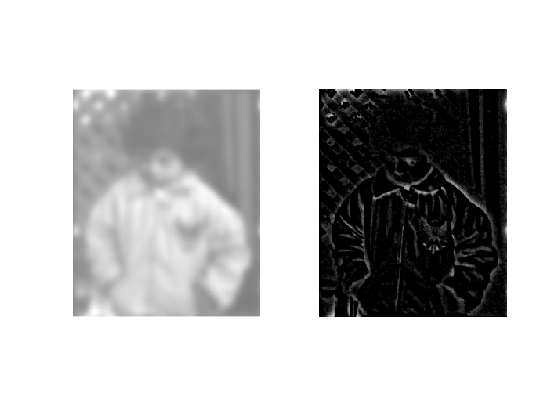

sharp_image = real(f)-x;
sharp_image = sharp_image;
sharp_image_norm=sharp_image/max(sharp_image(:));
imshow(sharp_image_norm)

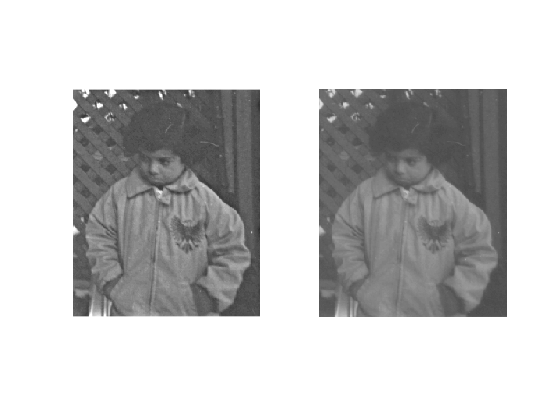

unsharp = x-0.5*real(f);
unsharp = unsharp*2;
subplot(121)
imshow(unsharp)
subplot(122)
imshow(x)

# And now for something completely different...

 
$$\frac{-4s+8}{s^2+6s+8}$$


[r,p,k] = residue([-4, 8],[1, 6, 8])
pzmap([-4, 8],[1, 6, 8])
syms t a s
f = exp(-a*t);
laplace(f)
ilaplace(-4*s+8/(s^2+6*s+8))
